## **2.1 Probabilidade condicional, independência**

**1. Considere a variável aleatória X correspondente à face que fica para cima no lançamento de 1 dado. Usando os valores teóricos:**

(a) produza um gráfico, em Matlab, que represente a função massa de probabilidade de X;

%% Um dado tem 6 lados e, com faces de 1 a 6 e equiprováveis 
%% de calhar (P(1) = 1/6 = P(2) = 1/6 ...). Sabendo isto, podemos
%% representar a função probabilidade de X da seguinte forma:
X = [1 2 3 4 5 6];
P = 1/6;
y = pdf("prob",X,P)

Error using makedist
Distribution name 'prob' is unrecognized.

Error in pdf (line 155)
            pd = makedist(name,varargin{:});

**2. Considere uma caixa contendo 90 notas de 5 Euros, 9 notas de 50 e 1 de 100.**

(a) Descreva o espaço de amostragem da experiência aleatória, retirar uma nota da caixa, e as probabilidades dos acontecimentos elementares.

%% Temos 100 acontecimentos elementares, todos equiprováveis que 
%% correspondem a calhar cada uma das notas {nota1, nota2, ..., nota100}
%% , cuja probabilidade é 1/100

   (b) Considere agora a variável aleatória X como sendo o valor de uma nota retirada à sorte da caixa acima descrita. Descreva o espaço de amostragem e a função massa de probabilidade de X.

%% p(5) = 0.900
%% p(50) = 0.090
%% p(100) = 0.010

(c) Determine a função distribuição acumulada de X e efectue a sua representação gráfica em Matlab.

x = [5 50 100];
px = [0.90 0.09 0.01];
fx = cumsum(px)

stairs([0 x 110],[0 fx 1])
grid on
ylim([0 1.1])
xlim([0 110])
   

**3. Considere 4 lançamentos de uma moeda equilibrada. Seja X a variável aleatória representativa do número de coroas observados nos 4 lançamentos.**

(a) Estime por simulação a função massa de probabilidade pX (x) da variável aleatória X.

prob = 0.5;
N= 1e5;
probArray = zeros(5,1);
experiencias = rand(4,N) < prob;
for index = 1:1:5
    for i = 1:N
        column = experiencias(:,i);
        probArray(index) = probArray(index) + (sum(column) == (index-1));
    end
end

probArray = probArray / N

probArray =     0.0629
    0.2500
    0.3756
    0.2486
    0.0629


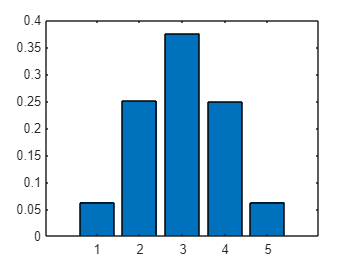

bar(probArray)


fprintf("f(0)= %.4f\n", probArray(1))

f(0)= 0.0629


fprintf("f(1)= %.4f\n", probArray(2))

f(1)= 0.2500


fprintf("f(2)= %.4f\n", probArray(3))

f(2)= 0.3756


fprintf("f(3)= %.4f\n", probArray(4))

f(3)= 0.2486


fprintf("f(4)= %.4f\n", probArray(5))

f(4)= 0.0629


(b) Estime o valor esperado, a variância e o desvio padrão de X com base em pX (x).

X = [0 1 2 3 4];

avg = X*probArray

avg = 1.9985

%% média de ((array de acontecimentos X - média (array de acontecimentos X)) ao quadrado)
sigma = ((X - avg).^2)

sigma =     3.9939    0.9970    0.0000    1.0030    4.0061


%% 
var = sigma*probArray

var = 1.0019

%% sqrt da Variância
desvioP = sqrt(var)

desvioP = 1.0009

(c) Identifique o tipo da distribuição da variável aleatória X e escreva a expressão teórica da respectiva função de probabilidade.

%% O tipo de distribuição é Binomial, com p=0.5 e n=4

(d) Calcule os valores teóricos da função massa de probabilidade de X e compare-os com os valores estimados por simulação obtidos em (a)

pArrayT = zeros(5,1);
for i = 0:1:4
    pArrayT(i+1) = nchoosek(4,i)*0.5^i*(1-0.5)^(4-i);
    fprintf("p(%d)= %.4f\n",i,pArrayT(i+1));
end

p(0)= 0.0625
p(1)= 0.2500
p(2)= 0.3750
p(3)= 0.2500
p(4)= 0.0625


(e) Calcule os valores teóricos de E[x] e de Var(X) e compare-os com os valores obtidos em (b).

X = [0 1 2 3 4];
avg = X*pArrayT;
var = ((X - avg).^2)*pArrayT;
desvioP = sqrt(var);

fprintf("Average= %.4f\n Variancia= %.4f\n Desvio Padrão= %.4f",avg,var,desvioP);

Average= 2.0000
 Variancia= 1.0000
 Desvio Padrão= 1.0000

(f) Com base nos valores teóricos da função massa de probabilidade desta distribuição, calcule:

i. a probabilidade de obter pelo menos 2 coroas;

ii. a probabilidade de obter até 1 coroa;

iii. a probabilidade de obter entre 1 e 3 coroas, inclusive.

pI = 0;
pII = 0;
pIII = 0;
for i=2:1:4
    pI = pI + nchoosek(4,i)*0.5^i*(1-0.5)^(4-i);
end

for i= [0 1]
    pII = pII + nchoosek(4,i)*0.5^i*(1-0.5)^(4-i);
end

for i = [1 2 3]
    pIII = pIII + nchoosek(4,i)*0.5^i*(1-0.5)^(4-i);
end

fprintf("Probabilidade de i) p= %.4f\n", pI)

Probabilidade de i) p= 0.6875


fprintf("Probabilidade de ii) p= %.4f\n", pII)

Probabilidade de ii) p= 0.3125


fprintf("Probabilidade de iii) p= %.4f", pIII)

Probabilidade de iii) p= 0.8750